clear;
close all; clc
[status,sheets] = xlsfinfo('Douglas-Proj.xls');
fprintf("Laura Douglas HW2 Part 2")

Laura Douglas HW2 Part 2

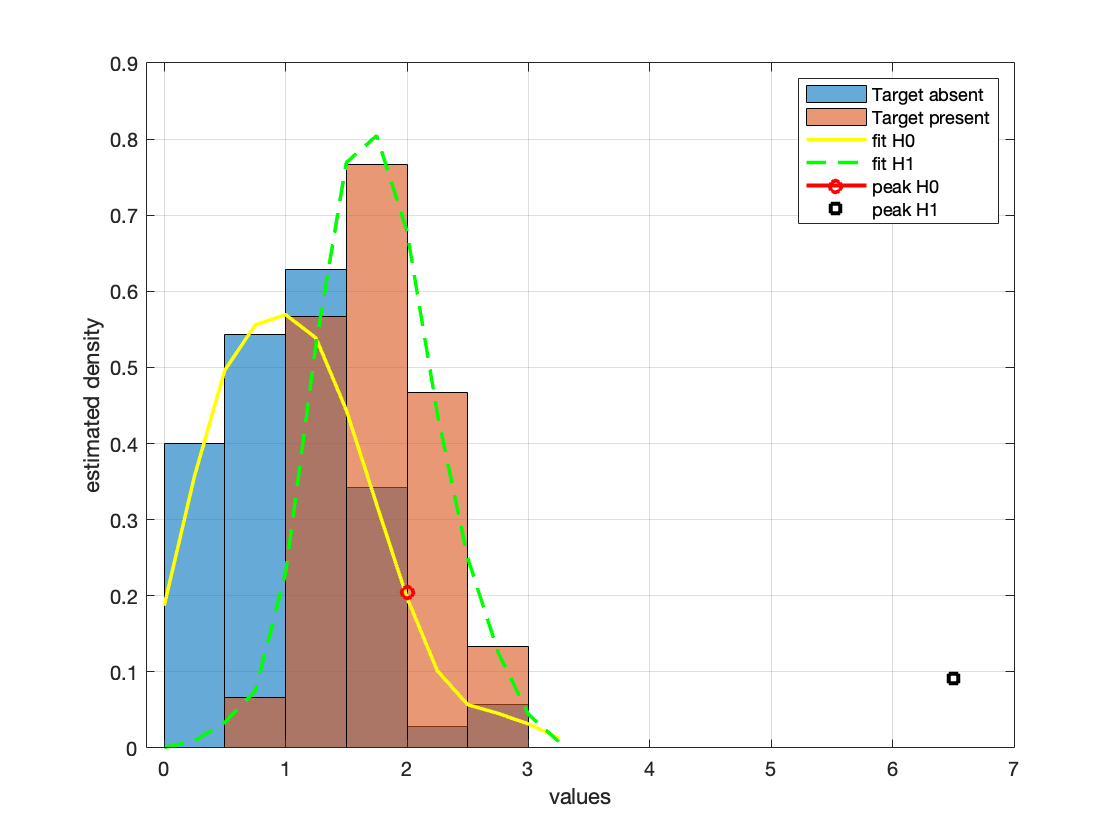

% the command to read the data
A=readmatrix('Douglas-Proj.xls','Sheet',1); % read the first sheet
x=A(1:70);% get the first 60 rows of 1st column
y=A(71:end); % get the next 50 of 1st column
A=A(:);
% x and y are of different lengths. Because of this, y contains NaN
y=y(~isnan(y)); % suppress the NaN
histogram(x, 'normalization', 'pdf');
hold on 
grid on 
histogram(y, 'normalization', 'pdf');
% xlim([0,25])
% ylim([0,0.3])
xx=0:0.25:1.2*max(A);% get the x-coordinates to get the ksdensity
fx1=ksdensity(x,xx);
plot(xx,fx1,'-y','linewidth',1.75)
fy1=ksdensity(y,xx);
plot(xx,fy1,'-g','linewidth',1.75, "LineStyle","--")
xlabel('values'),ylabel('estimated density');
peaks_fx1 = findpeaks(fx1);
peaks_fy1 = findpeaks(fy1);
plot(2, 0.2038, "red", "Marker","o", "LineWidth", 2)
plot(6.5, 0.0908, '*k', "Marker", "square", "LineWidth", 2)
legend('Target absent','Target present','fit H0','fit H1','peak H0','peak H1');

p1 = [1, 0.5693];
p2 = [1.75, 0.8046];
midpoint = (p1(:) + p2(:)).'/2;
intersection = [1.292, 0.557];

N0 = size(x,1);
N1 = size(y,1);
N = N0 + N1;
NfM = 16;
NcM = 41;
PH0 = N0/N;
PH1 = N1/N;
fprintf("Midpoint Threshold")

Midpoint Threshold

VtM = 4.25

VtM = 4.2500

fprintf('confusionMM = [(N0 - NfM), (N1 -NcM); (NfM), (NcM)]')

confusionMM = [(N0 - NfM), (N1 -NcM); (NfM), (NcM)]

confusionMM = [(N0 - NfM), (N1 -NcM); (NfM), (NcM)]

confusionMM =     54    19
    16    41


fprintf('errorrateM = (NfM + (N1 - NcM))/N')

errorrateM = (NfM + (N1 - NcM))/N

errorrateM = (NfM + (N1 - NcM))/N

errorrateM = 0.2692

fprintf('ppvM = NcM/(NfM + NcM)')

ppvM = NcM/(NfM + NcM)

ppvM = NcM/(NfM + NcM)

ppvM = 0.7193

pmM = NfM/110;
pfM = NcM/110;
fprintf('tranisitionmM = [(1 - pfM), pmM; pfM, (1-pmM)]')

tranisitionmM = [(1 - pfM), pmM; pfM, (1-pmM)]

tranisitionmM = [(1 - pfM), pmM; pfM, (1-pmM)]

tranisitionmM =     0.6273    0.1455
    0.3727    0.8545



fprintf("Intersection Threshold")

Intersection Threshold

VtI = 5

VtI = 5

NfI = 13;
NcI = 36;
fprintf('confusionMI = [(N0 - NfI), (N1 -NcI); (NfI), (NcI)]')

confusionMI = [(N0 - NfI), (N1 -NcI); (NfI), (NcI)]

confusionmI = [(N0 - NfI), (N1 -NcI); (NfI), (NcI)]

confusionmI =     57    24
    13    36


fprintf('errorratemI = (NfI + (N1 - NcI))/N')

errorratemI = (NfI + (N1 - NcI))/N

errorratemI = (NfI + (N1 - NcI))/N

errorratemI = 0.2846

fprintf('ppvI = NcI/(NfI + NcI)')

ppvI = NcI/(NfI + NcI)

ppvI = NcI/(NfI + NcI)

ppvI = 0.7347

pmI = NfI/110;
pfI = NcI/110;
fprintf('tranisitionmM = [(1 - pfI), pmI; pfI, (1-pmI)]')

tranisitionmM = [(1 - pfI), pmI; pfI, (1-pmI)]

tranisitionmI = [(1 - pfI), pmI; pfI, (1-pmI)]

tranisitionmI =     0.6727    0.1182
    0.3273    0.8818
